clear all 
clc;
syms L1 L2 L3   %Bruker Sym for å få symbolsk dh parameter. men da fungerer
%ikke robot.teach ;)

% L1 = 1.5; L2 = 0.8; L3 = 1.5; % Link lengder 

L(1) = Link([0,L1,0,pi/2]); %Theta D a Alpha
L(2) = Link([0,L2,0,-pi/2]);
L(3) = Link([0,L3,0,pi/2]);
L(4) = Link([0,-L2,0,-pi/2]);
ROBOT = SerialLink(L,'name','Robotarm') %SKRIVER UT DH TABELL Å LAGER SERIALLINK OBJECT


 
ROBOT = 
 
Robotarm:: 4 axis, RRRR, stdDH, slowRNE, Symbolic                
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|         L1|          0|       pi/2|          0|
|  2|         q2|         L2|          0|      -pi/2|          0|
|  3|         q3|         L3|          0|       pi/2|          0|
|  4|         q4|        -L2|          0|      -pi/2|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


q1 = 0; q2 = 0; q3 = 0; q4 = 0;  %LEDDDVINKLER = 0
q = [q1, q2, q3, q4];
T01 = ROBOT.A(1,q1)

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & -1 & 0\\ 0 & 1 & 0 & L_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T12 = ROBOT.A(2,q)

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & -1 & 0 & L_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T23 = ROBOT.A(3,q)

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & -1 & 0\\ 0 & 1 & 0 & L_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T34 = ROBOT.A(4,q)

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & -1 & 0 & -L_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


T04 = T01*T12*T23*T34    %Translasjon fra base frame til EE 

$$\left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & L_{1}+L_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

clc; clear all
%OPP NED ARM MED LENGDER FOR VISULASJON
L1 = 1.5; L2 = 0.8; L3 = 1.5; % Link lengder 

L(1) = Link([0,L1,0,pi/2]); %Theta D a Alpha
L(2) = Link([0,L2,0,-pi/2]);
L(3) = Link([0,L3,0,pi/2]);
L(4) = Link([0,-L2,0,-pi/2]);
ROBOT = SerialLink(L,'name','Robotarm')

 
ROBOT = 
 
Robotarm:: 4 axis, RRRR, stdDH, slowRNE                          
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        1.5|          0|     1.5708|          0|
|  2|         q2|        0.8|          0|    -1.5708|          0|
|  3|         q3|        1.5|          0|     1.5708|          0|
|  4|         q4|       -0.8|          0|    -1.5708|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


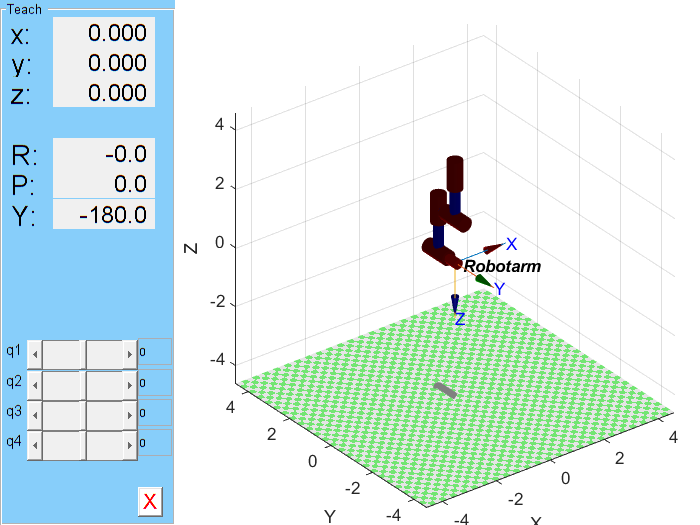


ROBOT.base = transl(0,0,3)*trotx(pi) ;% Snur robotarmen til å henge opp ned
ROBOT.plotopt = {'nobase'};  % Gjemmer base axis
ROBOT.teach   